Mp = 0.15;
zeta = -log(Mp)/(sqrt(pi^2 + log(Mp)^2))

zeta = 0.5169

ts = 4;
Wn = 4/(ts*zeta)

Wn = 1.9345

beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*Wn

xpoint = -1

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*Wn

ypoint = 1.6560

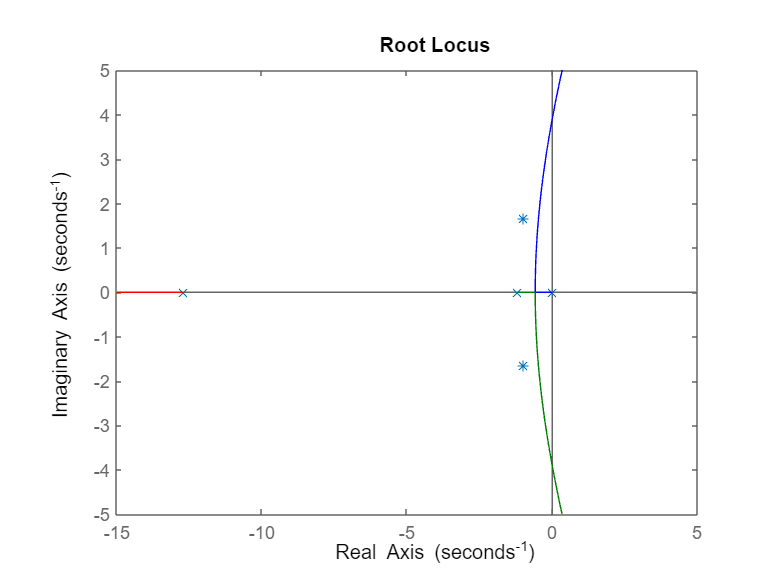

num1 = 15.25;
den1 = [1 13.9 15.24 0];
g1 = tf (num1,den1);
rlocusplot (g1);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%sisotool(g1)

teta_p = 44.5;
teta_z = 77.5;
x = ypoint/(tan((44.5*pi)/180));
p = x + 1

p = 2.6851

y = ypoint/(tan((77.5*pi)/180));
z = y + 1

z = 1.3671

s = -1 + 1.65j ;
num2 = 15.25*(s+z);
den2 = (s+p)*s*(s+1.2)*(s+12.7);
k = abs(den2/num2)

k = 3.4666

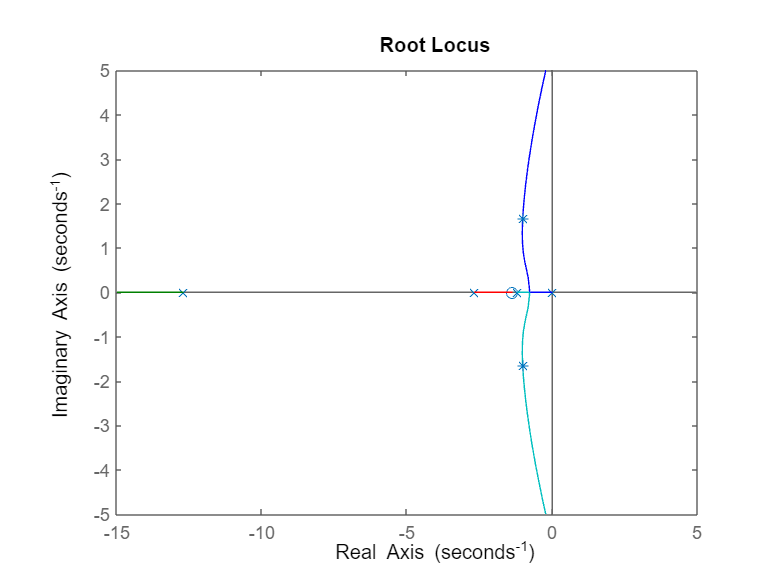

num3 = [k*15.25 k*15.25*z];
den3 = [1 13.9+p p*13.9+15.24 15.24*p 0];
g2 = tf(num3,den3);
rlocusplot (g2);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%sisotool(g2);

K_old = 1.766;
K_new = 34;
z2 = 0.1/10

z2 = 0.0100

p2 = (z2*K_old)/K_new

p2 = 5.1941e-04

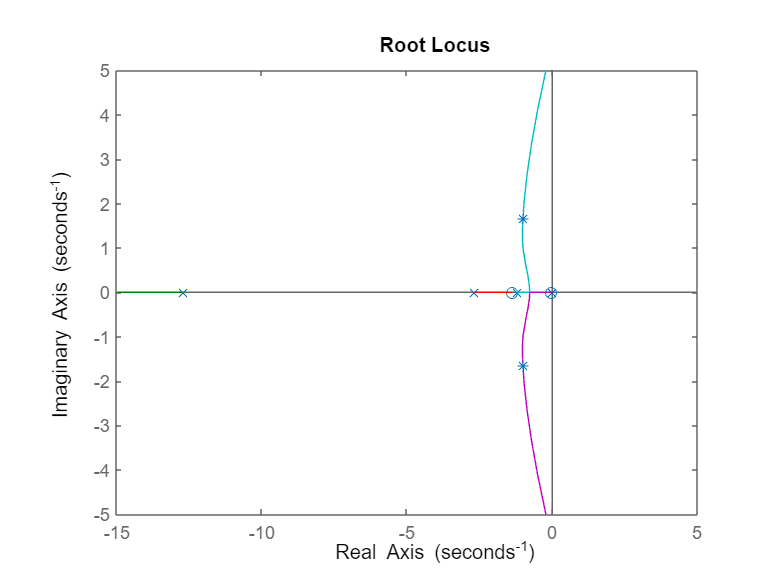

num4 = [52.8661 72.803 0.7227];
den4 = [1 16.5856 52.572 40.949 0.0213 0];
g3 = tf(num4,den4);
h = rlocusplot (g3);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

sisotool(g3)